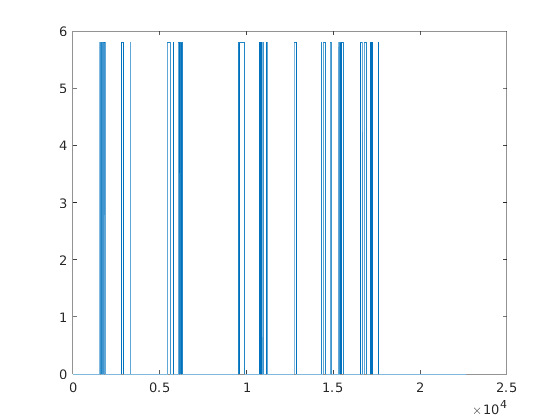

clear all;

bag= rosbag('2018-07-07-16-58-09.bag');
BrakeTopic= select(bag, 'Topic', '/cmd_brake_power');
BrakeMsg = readMessages(BrakeTopic,'DataFormat','struct');

brake_power= cellfun(@(m) double(m.BrakePower),BrakeMsg);

plot(brake_power)

% rosoutTopic= select(bag, 'Topic', '/rosout');
% logMsg = readMessages(rosoutTopic,'DataFormat','struct');
% log= cellfun(@(m) double(m.Log),logMsg);

Reference to non-existent field 'Log'.

Error in london_result_analysis (line 11)
log= cellfun(@(m) double(m.Log),logMsg);